## **Tube Classifier | Train & Test**

This Live Script allows new model training, batch testing, as well as single image tests. To get started, press 'run' in the section that corresponds to your intended output. The following sections can be run: 

- Train: trains a new model using the full MPDD set of images. Saves a new model along with a folder called 'testImages' containing the images used for validation and to be used for future batch testing.

- Batch Test: Performs a Batch test on the 'testImages' file. The function generates two confusion matrices, the first shows all classifications with a row summary displaying the percentage of correct/incorrect classifications. An additional confusion matrix only compares the pass/fail classifications. Finally, yield rates and defect rates are calculated and displayed. The escaped defect rate shows how many 'failed' parts were classified as a 'pass' by the AI classifier. Ideally, this value is 0.00%.

- Single Image Test: Classifies a single image and generates a detailed output report. Optionally, a comparison of the test set mask and generated mask can be displayed.

*Note: if you downloaded the test images set and provided model from the GitHub, you do not need to train a new model, otherwise, download the full MPDD set and begin with this function.*

Testing can be further personalized using the drop-downs/sliders listed in each section (if any).

### Train Model

% ---> Run Training Section

 

% ---> USER SETTINGS 

chosenDataset = "tubes"; % Only 1 Dataset as of 7/26/26

% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Obtain the file location of the dataset. 
fileLoc = sprintf("MPDD/%s/test", chosenDataset);

% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Creates an AI Model in local directory called "tubeClassifierNet.mat"
% saves a test set used for validation as a folder 'testImages'
training(ds);

### Batch Testing

labels = "good"

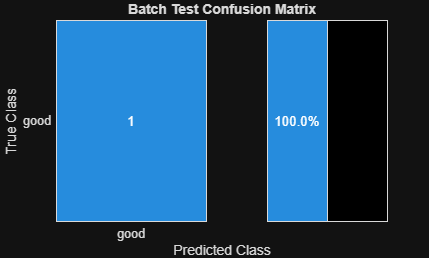

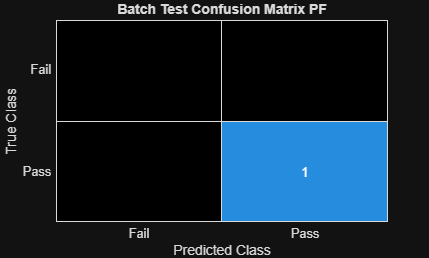

Actual Yield: 100.0%
Predicted Yield 100.0%

Defect Rate: 0.0%
Escaped Defect Rate 0.0%



% ---> Run Training Section

 

% ---> USER SETTINGS 



% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Loads test image dataset
testDS = imageDatastore("testImages", 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Inspects the chosen batch using the trained AI model, outputs a confusion
% matrix
runBatchInspection(testDS);

### Single Image Inspection

% ---> Run Training Section

 

% ---> USER SETTINGS 

imageType = "malformedMetal"; % <-- Defect Type of Image
imgNum = 70; % <-- Number of image in subset
compareMasks = true; % <-- If enabled, a mask comparison will be displayed

% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Check that image number was valid
folder = sprintf("%s/MPDD/%s/test/%s", pwd, chosenDataset, imageType); % Finds Folder 
numFiles = numel(dir(folder)) - 2; % Count number of files in the folder 
if imgNum > numFiles 
   errMsg = sprintf("Warning: the selected category only has %d images. " + ...
       "The selected value '%d' has been set to 1 as a result.", numFiles, imgNum);
   disp(errMsg);
   imgNum = 1;
end

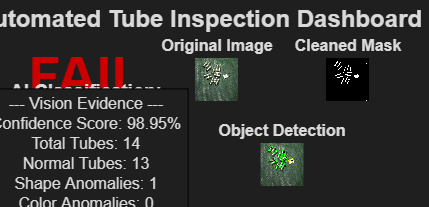


% Find and load chosen image
fileLoc = sprintf("%s/%s%03d.png", folder, imageType, imgNum);
img = imread(fileLoc);

% Generate Output
reportData = singleImageInspectionFunction(img, true);
displayInspectionOutput(img, reportData);

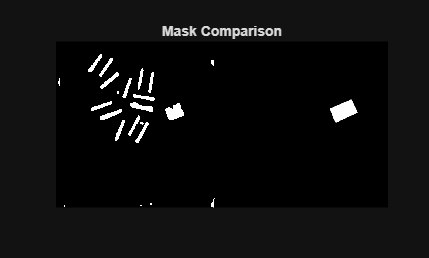


if compareMasks
    % Grab folder location for masks and loaf the mask image
    folder = sprintf("%s/MPDD/%s/%s_ground_truth/%sMask", ...
        pwd, chosenDataset, chosenDataset, imageType);
    fileLocMask = sprintf("%s/%s%03dMASK.png", folder, imageType, imgNum);
    imgMask = imread(fileLocMask);

    figure;
    montage({reportData.images.ImageMask, imgMask});
    title("Mask Comparison");
end